Sanusi Isiaka Olatunji 

m12435020

##  1a. Load the dataset into the workspace.

[fileName, filePath] = uigetfile(cd, 'Select one file');
fullFileName = fullfile(filePath, fileName);
load(fullFileName);


## 1b. Compute statistics and save them in a table.

data = dataTT{:,:};
rowsWithNans = sum(isnan(data),2);
data(rowsWithNans>0, :) = [];


% Calculate statistics
data_mean = mean(data);
data_median = median(data);
data_std = std(data);
data_iqr = iqr(data);
data_min = min(data);
data_max = max(data);

% Save statistics in a table
stats_table = table(data_mean, data_median, data_std, data_iqr, data_min, data_max, ...
    'VariableNames', {'Mean', 'Median', 'Std', 'IQR', 'Min', 'Max'});
disp(stats_table);

                                                            Mean                                                                                                                   Median                                                                                                              Std                                                                                                           IQR                                                                                                              Min                                                                                                            Max                                                  
    ____________________________________________________________________________________________________________________    __________________________________________________________________

## 1c. Produce plots (boxplot, line plot, and histogram).

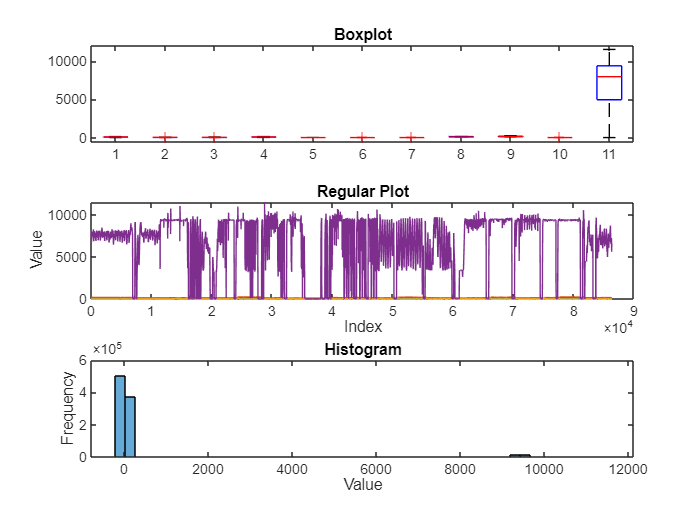

% Boxplot
figure;
subplot(3,1,1);
boxplot(data);
title('Boxplot');

% Line plot
subplot(3,1,2);
plot(data);
title('Regular Plot');
xlabel('Index');
ylabel('Value');

% Histogram with 50 bins
subplot(3,1,3);
histogram(data, 50);
title('Histogram');
xlabel('Value');
ylabel('Frequency');

1d. **Explain histogram for horizontal parts.**The histogram provides insight into data distribution. Peaks in the histogram indicate ranges with frequent values, suggesting "horizontal parts" or flat regions in the data.